%% Problem 1 %%
% (b)
% Setup for problem
format longE
n = 5;
x = linspace(0,1,n)';
f = sin(pi*x)';

% Use our function to compute interpolant weights
my_coeff = my_polyfit(x,f)

my_coeff =                          0
     3.084944665313014e+00
     5.752766734349279e-01
    -7.320442677495883e+00
     3.660221338747942e+00



% Compute true weights and reorder them to compare them to our weights
true_coeff = polyfit(x,f,n-1);
true_coeff = true_coeff(end:-1:1)'

true_coeff =      1.846421454946299e-16
     3.084944665313015e+00
     5.752766734349168e-01
    -7.320442677495862e+00
     3.660221338747931e+00



% Compute absolute error
absError = abs(my_coeff-true_coeff)

absError =      1.846421454946299e-16
     1.332267629550188e-15
     1.110223024625157e-14
     2.131628207280301e-14
     1.110223024625157e-14


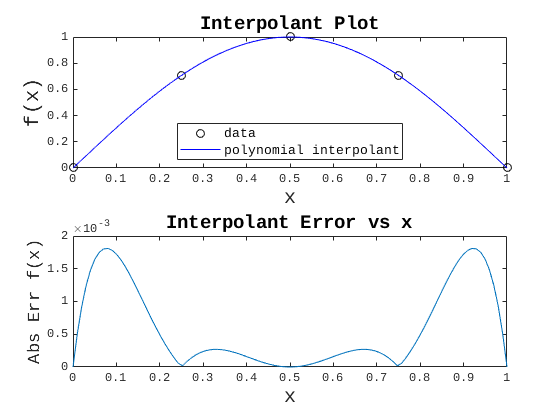

% (c)
% Setup
n = 5;
x = linspace(0,1,n)';
f = sin(pi*x)';

% Compute interpolant weights
my_coeff = my_polyfit(x,f);

% Compute function values from interpolant
z = linspace(0,1,100);
pz = my_polyval(my_coeff,z);

% Plot data and interpolant
figure(1), clf;
subplot(2,1,1)
plot(x,f,'ko', ...
     z,pz,'b-')
xlabel('x','FontSize',15)
ylabel('f(x)','FontSize',15)
title('\fontsize{14}Interpolant Plot')
legend('data','polynomial interpolant','Location','south','FontSize',10)

subplot(2,1,2)
plot(z,abs(pz'-sin(pi*z)))
xlabel('x','FontSize',15)
ylabel('Abs Err f(x)','FontSize',13)
title('\fontsize{14}Interpolant Error vs x')

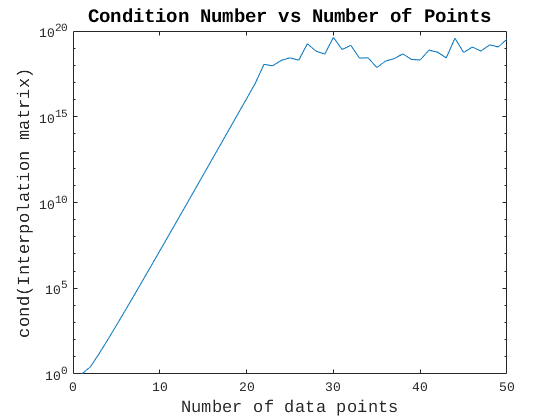

% (e)
% Turn of ill-conditioning warning
warning('off', 'MATLAB:nearlySingularMatrix')

% Number of data points to interpolate
n = 50;

% intialize condition number storage
conds = zeros;

% Compute condition numbers for different number of data points
for i = 1:n
    x = linspace(0,1,i)';
    f = sin(pi*x)';
    
    [coeff, conds(i)] = my_polyfit(x,f);
end

% Plot condition numbers for different number of points
figure()
semilogy(1:n,conds)
xlabel('Number of data points','FontSize',13)
ylabel('cond(Interpolation matrix)','FontSize',13)
title('\fontsize{14}Condition Number vs Number of Points')

%% Problem 2 %%
format shortE
% Conditions given in the problem
alpha = 0.1;
beta = 10.^(1:12);

% Preallocate space for errors
errs = zeros(1,12);

% Define b in Ax = b
b = [alpha;0;0;0;1];

% Compute errors of backward substitution for different values of beta
for i = 1:12
    A = [1 -1  0    alpha-beta(i)   beta(i); ...
         0  1 -1       0      0;  ...
         0  0  1      -1      0;  ...
         0  0  0       1     -1;  ...
         0  0  0       0      1];
     
    x = backwardsub(A,b);
    
    errs(i) = abs(x(1) - 1);
end 

% Create table of errors for different beta
table(beta',errs','VariableNames',{'Beta','Abs Err'})

ans = 12×2 table
       Beta        Abs Err  
    __________    __________

    1.0000e+01    4.4409e-16
    1.0000e+02    5.7732e-15
    1.0000e+03    2.2760e-14
    1.0000e+04    3.6382e-13
    1.0000e+05    5.8208e-12
    1.0000e+06    2.3283e-11
    1.0000e+07    3.7253e-10
    1.0000e+08    5.9605e-09
    1.0000e+09    2.3842e-08
    1.0000e+10    3.8147e-07
    1.0000e+11    6.1035e-06
    1.0000e+12    2.4414e-05


%% Problem 4 %% 
% setup
T = @(x,y) [1 0 0; ...
            0 1 0; ...
            x y 1];
R = @(theta) [ cos(theta) sin(theta) 0; ...
              -sin(theta) cos(theta) 0; ...
               0          0          1];
A = T(3,-1)*R(pi)*T(-3,1);
z = [2;2;1];

% (a)
% Solve for b
b = A*z

b =   -2.0000e+00
  -2.0000e+00
  -7.0000e+00


% (b)
% Compute LU factorization of A
[L,U,P] = lu(A)

L =    1.0000e+00            0            0
   2.0411e-17   1.0000e+00            0
   1.6667e-01   3.3333e-01   1.0000e+00


U =   -6.0000e+00   2.0000e+00   1.0000e+00
            0  -1.0000e+00  -2.0411e-17
            0            0  -1.6667e-01


P =      0     0     1
     0     1     0
     1     0     0


% (c)
% Use LU to solve for x
y = forwardsub(L, P*b);
x = backwardsub(U, y)

x =    2.0000e+00
   2.0000e+00
   1.0000e+00



% Compute error in x
err = abs(x-z)

err =             0
   4.4409e-16
   4.4409e-16


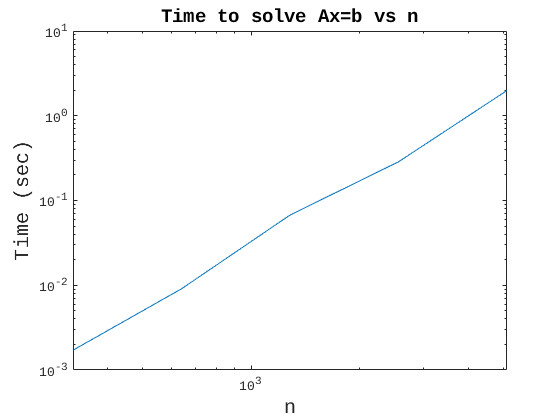

%% 5 %%
format short
% Store the differnt sizes of matrices
n = [320,640,1280,2560,5120];
% Compute time to solve nxn system of equations for different n
times = zeros(length(n),1);
for i = 1:length(n)
    A = rand(n(i),n(i));
    b = rand(n(i),1);
    
    tic
        A\b;
    times(i) = toc;
end

% Plot solve time for different n
figure()
loglog(n,times)
title('\fontsize{14}Time to solve Ax=b vs n')
xlabel('n','FontSize',15)
ylabel('Time (sec)','FontSize',15)
xlim([320,5120])


% Display different time table
table(n',times,'VariableNames',{'n','Time elapsed'})

ans = 5×2 table
     n      Time elapsed
    ____    ____________

     320      0.001713  
     640      0.009082  
    1280      0.067341  
    2560       0.28624  
    5120        1.9874  



% Compute average ratio in solving time from 2n to n
avgRatio = mean(times(2:5) ./ times(1:4))

avgRatio = 5.9776


% Approximate solve time for 20480x20480 sytem of equations
estTime = avgRatio^2 * times(5)

estTime = 71.0149

%% 6 %%
% Declare rand 10x10 matrix
A = rand(10);

% Compute smallest eigenvalue in absolute value using inverse iteration
lambda = inversePower(A)

lambda = 0.1104


% Compute true smallest eigenvalue in absolute value
trueLambda = eigs(A,1,'sm')

trueLambda = 0.1759 + 0.1135i


% Compute absolute error of eigenvalue calculation
absErr = abs(lambda - trueLambda)

absErr = 0.1310

%% Function Definitions %%

function [coeff, cond_num] = my_polyfit(x,f)
    % Compute number of points in x
    n = length(x);
    
    % Preallocate the polynomial matrix
    A = zeros(n);
    
    % Populate the polynomial matrix
    for i = 0:n-1
       A(:,i+1) = x.^i;
    end
    
    % Solve for the coefficients
    coeff = A\(f');
    
    % Compute condition number
    cond_num = cond(A);
end

function [pz] = my_polyval(coeff,z)
    % Size of coeff and z
    nc = length(coeff);
    nz = length(z);
    
    % Preallocate space for the powers
    powers = 0:nc-1;
    
    % Compute interpolant at each z_i
    pz = zeros(nz,1);
    for i=1:nz
        pz(i) = dot(coeff, z(i).^powers);
    end
end

function x = forwardsub(L, b) 
    % Get size of L
    n = length(L);
    
    % Initialize solution vector and then solve using forward substitution
    x = zeros(n,1);
    for i = 1:n
        x(i) = (b(i) - L(i,1:i-1)*x(1:i-1)) / L(i,i);
    end
end

function x = backwardsub(U, b) 
    % Get size of U
    n = length(U);
    
    % Initialize solution vector and then solve using backward substitution
    x = zeros(n,1);
    for i = n:-1:1
        x(i) = (b(i) - U(i,i+1:n)*x(i+1:n)) / U(i,i);
    end
end

function [lambda] = inversePower(A)
    n = length(A);
    x = rand(n,1);
    
    [L,U,P] = lu(A);
    for k = 1:100 % this is normally a ``while loop''
        y = forwardsub(L,P*x);
        y = backwardsub(U,y);
        x = y/norm(y);
    end
    
    lambda = x'*A*x;
end